# Parameters

clear;
L = 1.200; % Total length of the bridge in meters

num_axles = 6; % Number of axles
P= [135/2, 135/2, 135/2, 135/2, 182/6, 182/6]; 
dx = 0.001; % Step size for moving train in meters
num_sections = 1200; % Number of sections along the bridge for calculations
x = linspace(0, L, num_sections); % Discretize the bridge length
total_weight = P(1)+P(2)+P(3)+P(4)+P(5)+P(6) % Total weight of the train in Newtons

total_weight = 330.6667

% Axle positions (in meters)
x_train_spacing = [52, 228, 392, 568, 732, 908] / 1000; % Convert mm to meters
x_train_indices = [52, 228, 392, 568, 732, 908];

% Initialize envelopes
shear_force_max = zeros(num_sections, 1) -100000000; % Maximum shear force envelope
moment_max = zeros(num_sections, 1)-1000000000;      % Maximum bending moment envelope
shear_force = zeros(12, num_sections);
bending_moment = zeros(12, num_sections); 
train_loc = linspace(-50,290, 12);

% Moving train across the bridge
for train_pos = 1:12
    % Calculate axle positions along the bridge for current train position
    sum_Ma=0;
    for axles = 1:6 % Calculate the moment around point A to determine reaction at B
        sum_Ma = sum_Ma + (train_loc(train_pos)+x_train_indices(axles))*P(axles)*0.001;
    end
   % Reaction at B using moment equilibrium equation
    By = sum_Ma / L % Reaction at B (right support)
    % Sum of vertical forces for equilibrium to find Ay
    sum_Fy = total_weight; % Sum of all downward forces (total weight of train)
    Ay = sum_Fy - By % Reaction at A (left support)
    
    % Calculate shear force and bending moment at each section
    shear_force(train_pos, 1:train_loc(train_pos)+x_train_indices(1)) = Ay;
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(1):train_loc(train_pos)+x_train_indices(2)) = Ay-P(1);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(2):train_loc(train_pos)+x_train_indices(3)) = Ay-P(1) -P(2);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(3):train_loc(train_pos)+x_train_indices(4)) = Ay-P(1)-P(2)-P(3);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(4):train_loc(train_pos)+x_train_indices(5)) = Ay-P(1)-P(2)-P(3)-P(4);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(5):train_loc(train_pos)+x_train_indices(6)) = Ay-P(1)-P(2)-P(3)-P(4)-P(5);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(6):1199) = Ay-P(1)-P(2)-P(3)-P(4)-P(5)-P(6);
    shear_force(train_pos,1200)=Ay-P(1)-P(2)-P(3)-P(4)-P(5)-P(6)+ By;
    

    %bending moment by integrating shear force
    for i = 1:1200
        bending_moment(train_pos, i) = -trapz(shear_force(train_pos, 1:i))*0.001;
    end
    
   
    for i = 1:1200
        % Update envelopes if current values exceed stored max/min values
        if shear_force(train_pos, i)>shear_force_max(i) 
            shear_force_max(i) = shear_force(train_pos, i);
        end
        if bending_moment(train_pos, i)>moment_max(i) 
            moment_max(i)=bending_moment(train_pos, i);
        end
    end
    
end

By = 97.4278

Ay = 233.2389

By = 105.9449

Ay = 224.7217

By = 114.4621

Ay = 216.2045

By = 122.9793

Ay = 207.6874

By = 131.4965

Ay = 199.1702

By = 140.0136

Ay = 190.6530

By = 148.5308

Ay = 182.1359

By = 157.0480

Ay = 173.6187

By = 165.5652

Ay = 165.1015

By = 174.0823

Ay = 156.5843

By = 182.5995

Ay = 148.0672

By = 191.1167

Ay = 139.5500


%setting up variables to plot for shear envelope
shear1 = shear_force(1, 1:1200);
shear2=shear_force(2, 1:1200);
shear3=shear_force(3, 1:1200);
shear4=shear_force(4, 1:1200);
shear5=shear_force(5, 1:1200);
shear6 = shear_force(6, 1:1200);
shear7=shear_force(7, 1:1200);
shear8=shear_force(8, 1:1200);
shear9=shear_force(9, 1:1200);
shear10=shear_force(10, 1:1200);
shear11=shear_force(11, 1:1200);
shear12=shear_force(12, 1:1200);

%setting up variables to plot for bending envelope
bending1 = bending_moment(1, 1:1200);
bending2 = bending_moment(2, 1:1200);
bending3 = bending_moment(3, 1:1200);
bending4 = bending_moment(4, 1:1200);
bending5=bending_moment(5, 1:1200);
bending6 = bending_moment(6, 1:1200);
bending7=bending_moment(7, 1:1200);
bending8=bending_moment(8, 1:1200);
bending9=bending_moment(9, 1:1200);
bending10=bending_moment(10, 1:1200);
bending11=bending_moment(11, 1:1200);
bending12=bending_moment(12, 1:1200);


%plotting shear envelope of 12 iterations
max(abs(shear12))

ans = 191.1167

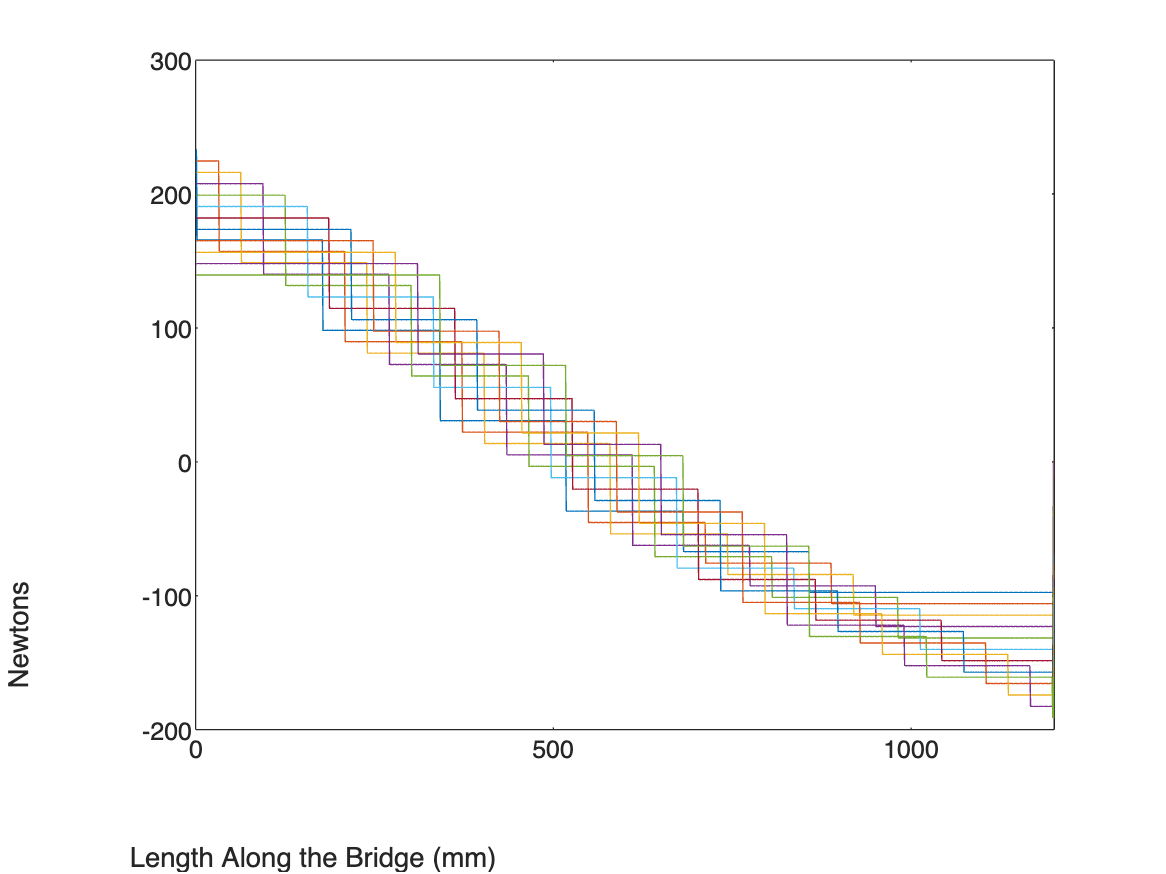

figure;
title("Shear Force Envelope of Matboard Bridge")
plot(shear1)
hold on;
plot(shear2) 
hold on;
plot(shear3)
hold on;
plot(shear4)
hold on;
plot(shear5)
hold on;
plot(shear6)
hold on;
plot(shear7)
hold on;
plot(shear8) 
hold on;
plot(shear9)
hold on;
plot(shear10)
hold on;
plot(shear11)
hold on;
plot(shear12)
hold on;
xlabel("Length Along the Bridge (mm)")
ylabel("Newtons")

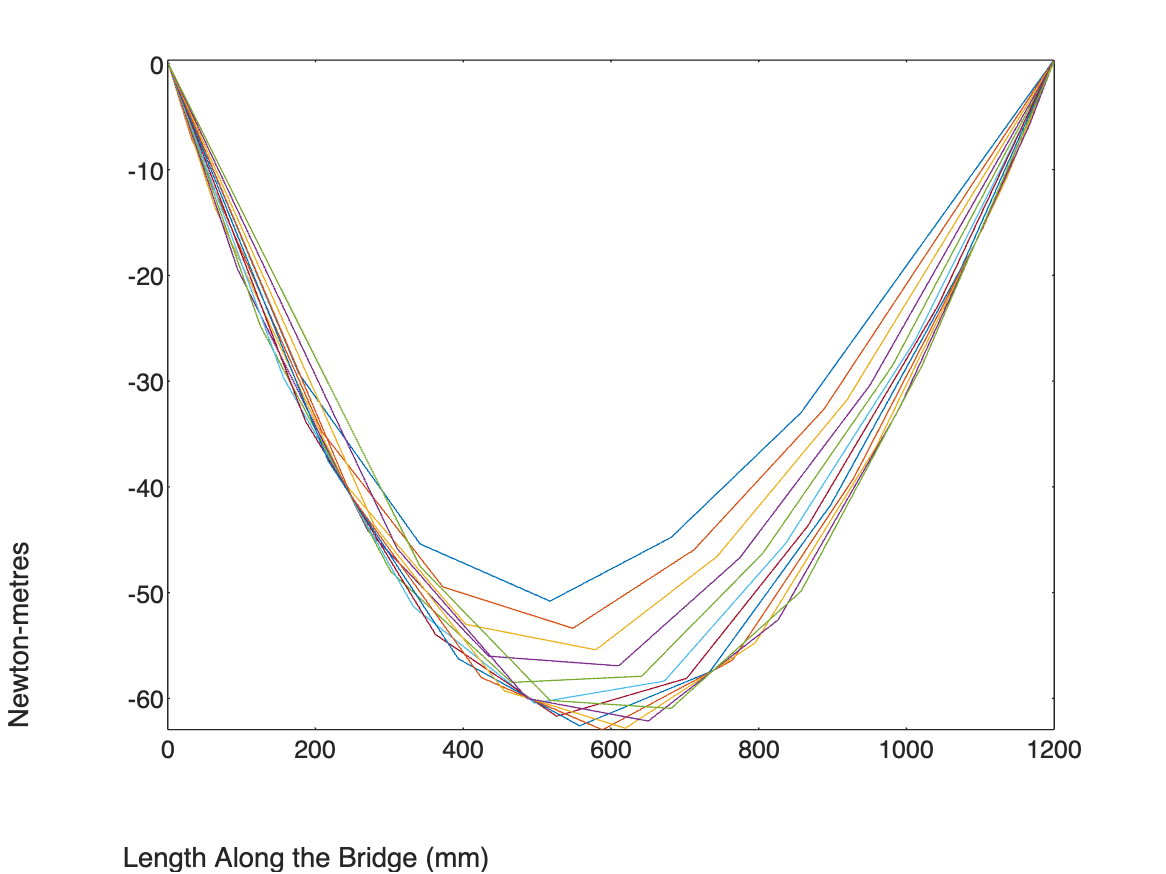


%plotting moment envelope of 12 iterations
figure;
plot(bending1)
hold on;
plot(bending2)
hold on;
plot(bending3)
hold on;
plot(bending4)
hold on;
plot(bending5)
hold on;
plot(bending6)
hold on;
plot(bending7)
hold on;
plot(bending8)
hold on;
plot(bending9)
hold on;
plot(bending10)
hold on;
plot(bending11)
hold on;
plot(bending12)
xlabel("Length Along the Bridge (mm)")
ylabel("Newton-metres")

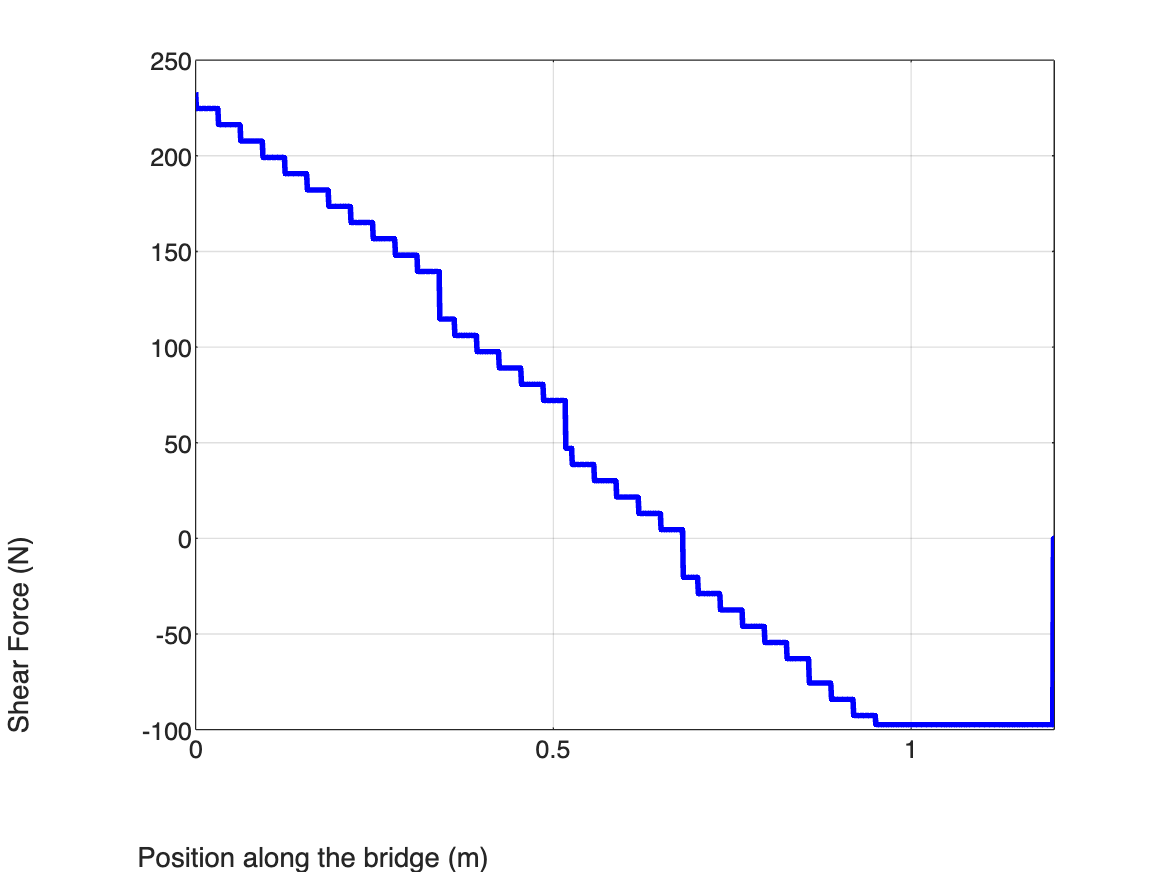



% Plotting the shear force envelope
figure;
plot(x, shear_force_max, 'b-', 'LineWidth', 2);
xlabel('Position along the bridge (m)');
ylabel('Shear Force (N)');
grid on;
hold off;

max(moment_max)

ans = 0.3499

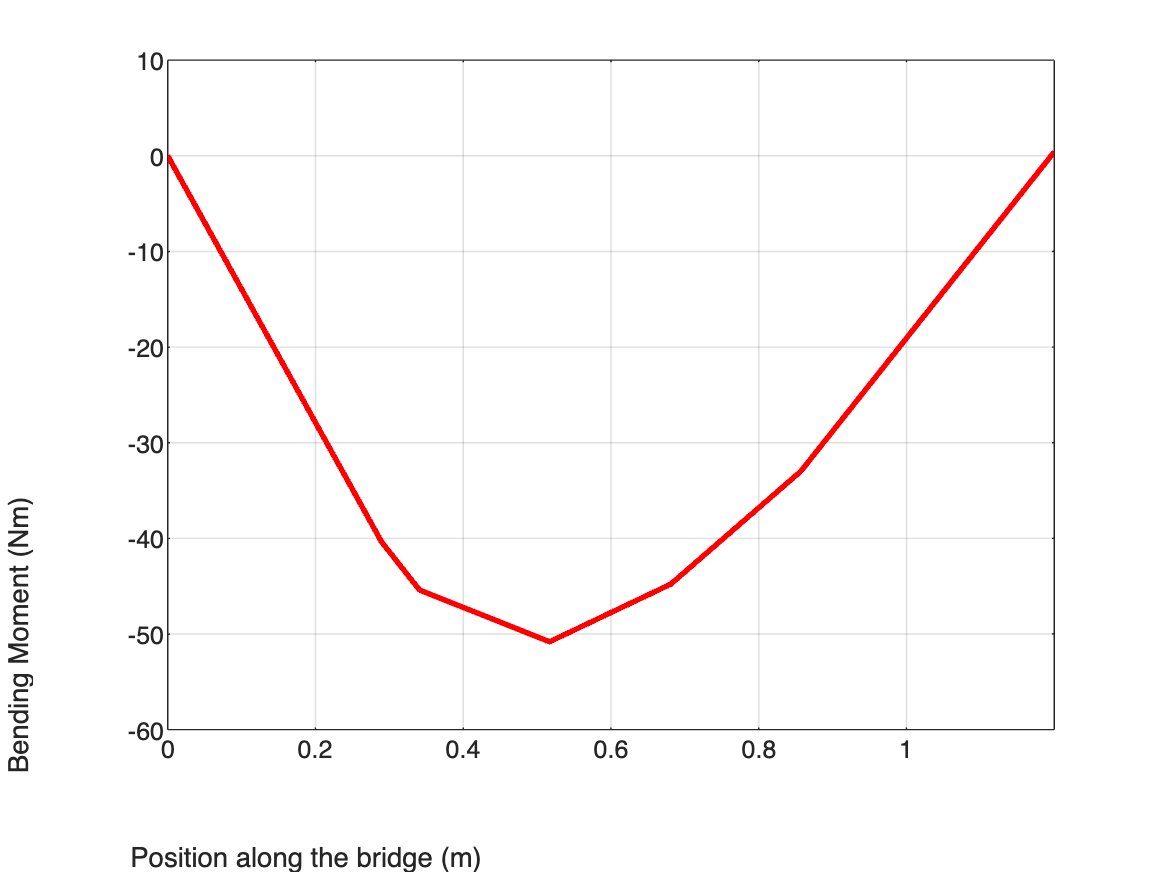

% Plotting the bending moment envelope
figure;
plot(x, moment_max, 'r-', 'LineWidth', 2);
xlabel('Position along the bridge (m)');
ylabel('Bending Moment (Nm)');

grid on;
hold off;

## 3. Calculate Sectional Properties (see report or drawings for reference)

DESIGN A 

%dimensions
flange = 110;
thick=1.27;
height=60;
gluetab=5;
b=80;
%split into areas
A1A = flange*thick;
A2A= (gluetab)*thick; %need 4
A3A=(height - 4*thick)*thick;%need 2
A4A=(height-6*thick)*thick; %need 2
A5A=(b-6*thick)*thick;
A6A = gluetab*thick; %need 2
A7A = (b-4*thick)*thick;
A8A= b*thick; %need 2
%calculate distance of centroids of each area from bottom
y1botA = height-thick/2;
y2botA = height-thick-thick/2;
y3botA = height/2;
y4botA = (height-6*thick)/2 + 4*thick;
y5botA = thick*3 + thick/2;
y7botA = thick*2 + thick/2;
y6botA = thick*2 + gluetab/2;
y8botA = thick + thick/2;
y9botA = thick/2;
%calculate ybar, ytop, ybot
ybarA = (A1A*y1botA + 4*A2A*y2botA + 2*A3A*y3botA + 2*A4A*y4botA+A5A*y5botA + 2*A6A*y6botA+A7A*y7botA + A8A*y8botA + A8A*y9botA)/(A1A+4*A2A+2*A3A+2*A4A+A5A+2*A6A+A7A+2*A8A)% ybar. location of centroidal axis from the bottom, changed I to 2*A4 and 2*a5

ybarA = 22.7773

ybotA = ybarA

ybotA = 22.7773

ytopA = height -ybarA

ytopA = 37.2227

% I calculations from each area
y1A=abs(ybarA-y1botA);
y2A=abs(ybarA-y2botA);
y3A=abs(ybarA-y3botA);
y4A=abs(ybarA-y4botA);
y5A=abs(ybarA-y5botA);
y6A=abs(ybarA-y6botA);
y7A =abs(ybarA-y7botA);
y8A=abs(ybarA-y8botA);
y9A =abs(ybarA-y9botA);
I1A=flange*thick^3/12;
I2A=(gluetab)*thick^3/12;
I3A=(height-6*thick)^3*thick/12;
I4A=(height-6*thick)^3*thick/12;
I5A=thick^3*(b-6*thick)/12;
I6A=gluetab^3 * thick/12; 
I7A=thick^3*(b-4*thick)/12;
I8A = thick^3*b/12;
IA =A1A*y1A^2+2*A2A*(thick+thick+2.5)^2 + 2*A2A*y2A^2+2*A3A*y3A^2+2*A4A*y4A^2+A5A*y5A^2+2*A6A*y6A^2 + A7A*y7A^2 + A8A*y8A^2 + A8A*y9A^2+I1A+4*I2A+2*I3A+2*I4A+I5A+2*I6A+I7A+2*I8A%changed to 2A4, 2A5

IA = 4.4651e+05


% Q at centroidal axes
QcentA = A1A*(ytopA-thick/2) + 2*A2A*(ytopA-thick-thick/2) + 4*(ytopA-2*thick)*thick*(ytopA-2*thick-(ytopA-2*thick)/2)

QcentA = 8.6152e+03

% Q at glue location
Qglue1A= A6A*(ytopA-thick/2);
Qglue2A=A8A*(ybarA-thick/2);
Qglue3A=A8A*(ybarA-thick/2)+(A7A+thick^2)*(ybarA-thick-thick/2);
Qglue4A=Qglue3A + gluetab/2 * thick *(ybarA-2*thick-gluetab/2);
QglueA = [Qglue1A, Qglue2A, Qglue3A, Qglue4A];
%take the maximum value to use to predict for worst case
maxQglueA = max(QglueA);
%% 5. Material and Thin Plate Buckling Capacities
E = 4000;
mu = 0.2;
a1=200;
a2=100

a2 = 100

T_max = 4;
T_gmax = 2;
%shear buckling cases
S_buck1aA = (4*pi^2*E)*(2*thick/75)^2/(12*(1-mu^2))

S_buck1aA = 15.7222

S_buck1bA = (4*pi^2*E)*(thick/5)^2/(12*(1-mu^2)) %for the small section between 80 and 75

S_buck1bA = 884.3714


S_buck2A =(0.425*pi^2*E)*(thick/((flange-75)/2))^2/(12*(1-mu^2))

S_buck2A = 7.6706

S_buck3A = (6*pi^2*E)*(thick/(ytopA-thick))^2/(12*(1-mu^2))

S_buck3A = 25.6568

T_buckA =(5*pi^2*E)*((thick/min(a1,a2))^2+(thick/(height-2*thick))^2)/(12*(1-mu^2))

T_buckA = 11.1342

%stress cases
Sigma_tensA = (abs(max(moment_max(100), moment_max(1100)))*1000)*ybotA/IA

Sigma_tensA = 0.4767

Sigma_compA = (abs(max(moment_max(100), moment_max(1100)))*1000)*ytopA/IA

Sigma_compA = 0.7790

Shear_centA= (max(shear_force_max))*QcentA/(IA*2*thick)

Shear_centA = 1.7717

Shear_glueA= (max(shear_force_max))*maxQglueA/(IA*2*thick) %using smallest area of glue

Shear_glueA = 0.8896


%% 6. FOS
FOS_tensA = 30/Sigma_tensA;
FOS_compA = 6/Sigma_compA;
FOS_shearA = 4/Shear_centA;
FOS_glueA = 2/Shear_glueA;
FOS_buck1A = 1/(Sigma_compA/min(S_buck1aA, S_buck1bA));
FOS_buck2A= 1/(Sigma_compA/S_buck2A);
FOS_buck3A = 1/(Sigma_compA/S_buck3A);
FOS_buckVA = 1/(Shear_centA/T_buckA);
All_FOS = [FOS_tensA, FOS_compA, FOS_shearA, FOS_glueA, FOS_buck1A, FOS_buck2A, FOS_buck3A, FOS_buckVA];


min_FOS = 2.2483

All_FOS =    62.9375    7.7025    2.2577    2.2483   20.1834    9.8471   32.9371    6.2843


DESIGN C

%set up areas and distance of each centroid from bottom
A1C = flange*thick;
y1botC = (height-thick/2);
A2C= (gluetab)*thick; %need 4
y2botC = (height-thick-thick/2);
A3C=(height-5*thick)*thick;%need 2
y3botC = (height-5*thick)/2+3*thick;
A4C=(height-4*thick)*thick; %need 2
y4botC = (height-4*thick)/2+3*thick;
A5C = (b-5)*thick 

A5C = 95.2500

y5botC= 2*thick+thick/2;
A6C = b*thick %need 2

A6C = 101.6000

y6botC = thick/2

y6botC = 0.6350

y7botC = thick+thick/2

y7botC = 1.9050

ybarC = (A1C*y1botC + 4*A2C*y2botC + 2*A3C*y3botC + 2*A4C*y4botC+A5C*y5botC+A6C*y6botC+A6C*y7botC)/(A1C+4*A2C+2*A3C+2*A4C+A5C+2*A6C);% ybar. location of centroidal axis from the bottom
ybotC = ybarC;
ytopC = height -ybarC;
% I calculations
y1C=abs(ybarC-y1botC);
y2C=abs(ybarC-y2botC);
y3C=abs(ybarC-y3botC);
y4C=abs(ybarC-y4botC);
y5C=abs(ybarC-y5botC);
y6C=abs(ybarC-y6botC);
y7C=abs(ybarC-y7botC);
I1C=flange*thick^3/12;
I2C=(gluetab)*thick^3/12; %have 4
I3C=(height-5*thick)^3*thick/12; %have 2
I4C=thick*(height-4*thick)^3/12; %have 2
I5C=(b-5)*thick^3/12;
I6C = b*thick^3/12;%need 2
IC =A1C*y1C^2+4*A2C*y2C^2+2*A3C*y3C^2+2*A4C*y4C^2+A5C*y5C^2+ A6C*y6C^2+A6C*y7C^2+I1C+4*I2C+2*I3C+2*I4C+I5C+2*I6C

IC = 4.3010e+05

% Q at centroidal axes
QCcent = A6C*2*(ybarC-thick)+4*(ybarC-2*thick)*thick*(ybarC-2*thick-(ybarC-2*thick)/2)

QCcent = 6.2684e+03

% Q at glue location
Qglue1C= A6C*2*(ybarC-thick)%larger

Qglue1C = 4.9272e+03

Qglue2C=A1C*(ytopC-thick/2)

Qglue2C = 4.7284e+03


%% 5. Material and Thin Plate Buckling Capacities
S_buck1C = (4*pi^2*E)*(thick/75)^2/(12*(1-mu^2))

S_buck1C = 3.9305

S_buck2C =(0.425*pi^2*E)*(thick/((flange-75)/2))^2/(12*(1-mu^2))

S_buck2C = 7.6706

S_buck3C = (6*pi^2*E)*(thick/(ytopC-thick))^2/(12*(1-mu^2))

S_buck3C = 30.0665

T_buck1C =(5*pi^2*E)*((thick/min(a1,a2))^2+(thick/(height-2*thick))^2)/(12*(1-mu^2))

T_buck1C = 11.1342


Sigma_tensC = (max(abs(moment_max))*1000)*ybotC/IC

Sigma_tensC = 3.0136

Sigma_compC = (max(abs(moment_max))*1000)*ytopC/IC

Sigma_compC = 4.0721

Shear_centC= (abs(shear_force_max(200)))*QCcent/(IC*2*thick)

Shear_centC = 0.9962

Shear_glueC= abs(shear_force_max(200))*Qglue1C/(IC*2*gluetab)

Shear_glueC = 0.1989

FOS_tensC = 30/Sigma_tensC;
FOS_compC = 6/Sigma_compC;
FOS_shearC = 4/Shear_centC;
FOS_glueC = 2/Shear_glueC;
FOS_buck1C = 1/(Sigma_compC/S_buck1C);
FOS_buck2C= 1/(Sigma_compC/S_buck2C);
FOS_buck3C = 1/(Sigma_compC/S_buck3C);
FOS_buckVC = 1/(Shear_centC/T_buck1C);
All_FOS = [FOS_tensC, FOS_compC, FOS_shearC, FOS_glueC, FOS_buck1C, FOS_buck2C, FOS_buck3C, FOS_buckVC];


All_FOS =     9.9550    1.4734    4.0152   10.0554    0.9652    1.8837    7.3835   11.1766


DESIGN B 

%resetting parameters because areas were calculated in different ways from
%above (due to complexity), but dimensions are still the same
flange = 110;
thick=1.27;
height=100;
gluetab=5;
b=100;
E=4000;
mu=0.2;
a=200

a = 200


%area and distance from bottom calculations
A1B = flange*thick;
y1botB = (height-thick/2);
A2B= (gluetab)*thick; %need 2
y2botB = (height-thick-thick/2);
A3B=(height-4*thick)*thick;%need 2
y3botB = (height-4*thick)/2+thick*3;
A4B=b*thick; %need 2
y4botB= thick/2;
ybarB = (A1B*y1botB + 2*A2B*y2botB + 2*A3B*y3botB + A4B*y4botB)/(A1B+2*A2B+2*A3B+A4B);% ybar. location of centroidal axis from the bottom
ybotB = ybarB;
ytopB = height + thick-ybarB;
% I calculations
y1B=abs(ybarB-y1botB);
y2B=abs(ybarB-y2botB);
y3B=abs(ybarB-y3botB);
y4B=abs(ybarB-y4botB);
I1B=flange*thick^3/12;
I2B=(gluetab)*thick^3/12; %have 2
I3B=(height-4*thick)^3*thick/12; %have 2
I4B=b*(thick)^3/12; %have 2
IB =A1B*y1B^2+2*A2B*y2B^2+2*A3B*y3B^2+A4B*y4B^2+I1B+2*I2B+2*I3B+2*I4B;
% Q at centroidal axes
QBcent = 2*thick*b*(ybarB-thick)+2*thick*(ybarB-2*thick)*((ybarB-2*thick)-(ybarB-2*thick)/2);
% Q at glue location
Qglue1B = flange*thick*(ytopB-thick/2);
Qglue2B = b*thick*(ybarB-thick/2);
maxQglueB = max(Qglue1B, Qglue2B);

%% 5. Material and Thin Plate Buckling Capacities
S_buck1B = (4*pi^2*E)*(thick/40)^2/(12*(1-mu^2));
S_buck2B =(0.425*pi^2*E)*(thick/((flange-75)/2))^2/(12*(1-mu^2));
S_buck3B = (6*pi^2*E)*(thick/(ytopB-thick))^2/(12*(1-mu^2));
T_buck1B =(5*pi^2*E)*((thick/a)^2+(thick/(height-2*thick))^2)/(12*(1-mu^2));

Sigma_tensB = (max(moment_max)*1000)*ybotB/IB;
Sigma_compB = (max(moment_max)*1000)*ytopB/IB;
Shear_centB= (abs(max(shear_force_max)))*QBcent/(IB*2*thick);
Shear_glueB= (abs(max(shear_force_max)))*maxQglueB/(IB*2*gluetab);
FOS_tensB = 30/Sigma_tensB;
FOS_compB = 6/Sigma_compB;
FOS_shearB = 4/Shear_centB;
FOS_glueB = 2/Shear_glueB;
FOS_buck1B = 1/(Sigma_compB/S_buck1B);
FOS_buck2B= 1/(Sigma_compB/S_buck2B);
FOS_buck3B = 1/(Sigma_compB/S_buck3B);
FOS_buckVB = 1/(Shear_centB/T_buck1B);
All_FOS = [FOS_tensB, FOS_compB, FOS_shearB, FOS_glueB, FOS_buck1B, FOS_buck2B, FOS_buck3B, FOS_buckVB];
%% 7. MIN FOS values of the entire bridge

All_FOS = 1.0e+03 *

    1.3861    0.3040    0.0023    0.0110    0.7001    0.3886    0.7595    0.0021


All_FOSbridge = [min([FOS_tensB, FOS_tensC, FOS_tensA]), min([FOS_compB, FOS_compC, FOS_compA]), min([FOS_shearB, FOS_shearA, FOS_shearC]), min([FOS_glueB, FOS_glueA, FOS_glueC]), min([FOS_buck1B, FOS_buck1A, FOS_buck1C]), min([FOS_buck2B, FOS_buck2A, FOS_buck2C]), min([FOS_buck3B, FOS_buck3A, FOS_buck3C]), min([FOS_buckVB, FOS_buckVA, FOS_buckVC])]

All_FOSbridge =     9.9550    1.4734    2.2577    2.2483    0.9652    1.8837    7.3835    2.0520


All_FOSbridge =     9.9550    1.4734    2.2577    2.2483    0.9652    1.8837    7.3835    2.0520
